## Implementación digital del filtro:

y*(t) = b1 x*(t) + b2 x*(t-T) - a1 y*(t-T) - a2 y*(t-2T)

### Inicialización

clear
close all
import java.lang.*; %Librería para los delay

%Definición de los coeficientes
a1 = 1;
a2 = 2;
b1 = 1;
b2 = 2;

%Definición del periodo de muestreo T
T = 0.1;

%Inicialización de valores "pasados" para el primer ciclo
x_init = 0;
x_init2 = 0;
y_init = 0;
y_init2 = 0;

%Definición de arrays que representarán a los registros
x = [];
y = [];

%Se agregan los valores iniciales a los registros
x = [x x_init x_init2];
y = [y y_init y_init2];

### Ciclo para el cálculo de la salida

%Mientras no hayan pasado n iteraciones:
iter = 30;
while (iter>0)    
    x_actual = ADC();   %Se lee la entrada actual
    x_ant = x(end);     %Se lee la entrada anterior
    y_ant = y(end);     %Se lee la salida anterior
    y_ant2 = y(end-1);  %Se lee la salida tras-anterior
    
    %Se calcula la salida actual
    y_actual = b1*x_actual + b2*x_ant - a1*y_ant - a2*y_ant2;
    
    %Se guardan los valores actuales en los registros
    x = [x x_actual];
    y = [y y_actual];
    iter = iter - 1;
    
    %Se aplica el delay de T segundos (periodo de muestreo)
    Thread.sleep(T*1000);
end

%Mostrar los valores de los registros
fprintf('Los valores de la entrada son:');

Los valores de la entrada son:

fprintf('%g,', x);

0,0,0.637709,0.957694,0.240707,0.676122,0.289065,0.671808,0.69514,0.0679928,0.25479,0.22404,0.667833,0.844392,0.344462,0.78052,0.675332,0.00671531,0.60217,0.386771,0.915991,0.00115106,0.462449,0.424349,0.460916,0.77016,0.322472,0.784739,0.471357,0.0357627,0.175874,0.721758,


fprintf('Los valores de la salida son:');

Los valores de la salida son:

fprintf('%g,', y);

0,0,0.637709,1.5954,-0.714726,-1.31854,4.38931,-0.502281,-6.23757,8.70041,4.16551,-20.8327,13.6176,30.2279,-55.4298,-3.55649,116.653,-108.182,-124.507,342.463,-91.7586,-591.334,775.316,408.701,-1958.02,1142.31,2775.59,-5058.79,-490.358,10608.9,-9627.95,-11588.8,

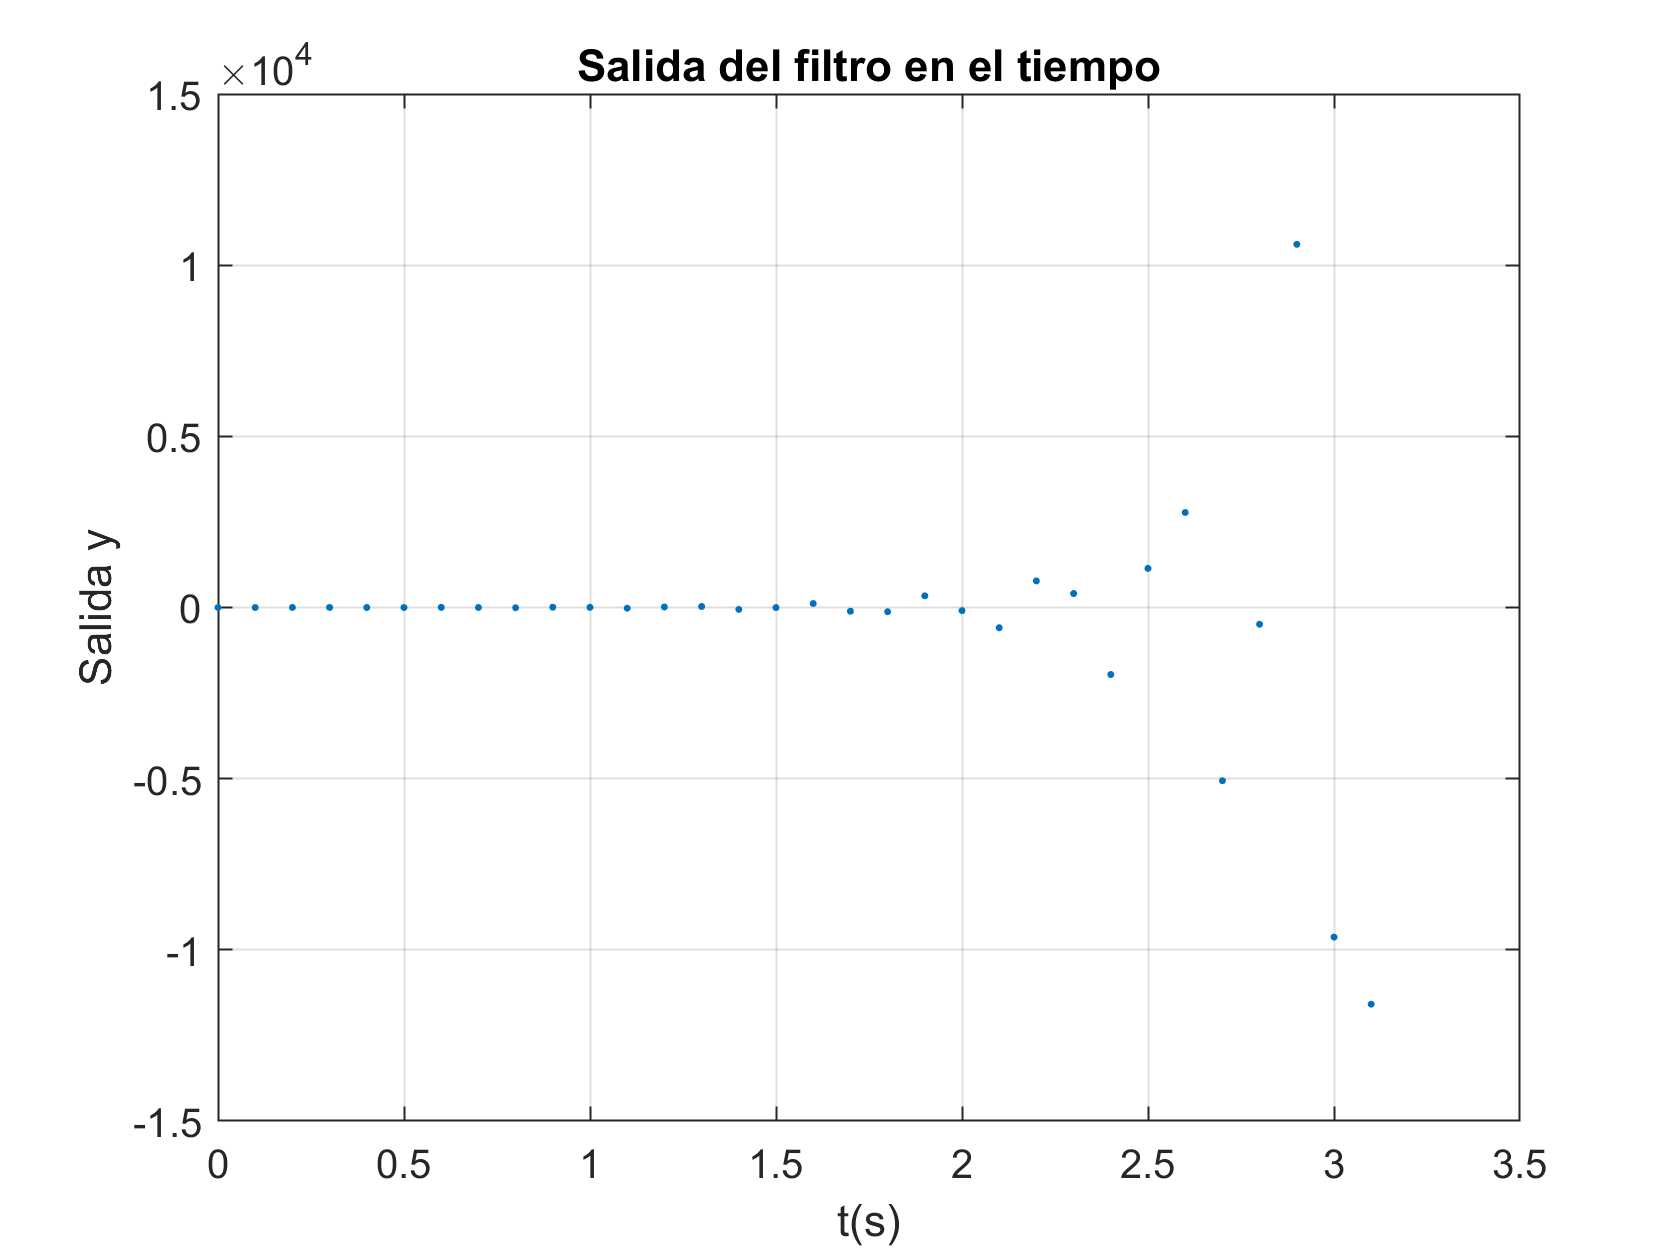


%Gráfico salida vs. tiempo
t = 0:T:T*(length(y)-1);    %Intervalos determinados por periodo de muestreo
plot(t,y,'.')
grid on
title('Salida del filtro en el tiempo')
xlabel('t(s)')
ylabel('Salida y')

function x = ADC()
    %Se generan número aleatorios que representan a las
    %lecturas que realizaría el ADC
    x = rand();
end